# WSHP Models

## 🚀 Initialization

clc; clear all;

% Add path to subfunction
addpath('../matlab_subfunc');

% Get a list of all files in the data folder
files = dir('*.csv');

## 🧹 Preprocess

% Initialize an empty array of structs
fileData = struct('fileName', {}, ...
                  'error', {}, ...
                  'acc_error', {}, ...
                  'inlet_water_temp', {}, ...
                  'return_air_temp', {}, ...
                  'return_air_hr', {}, ...
                  'sim_zone_temp', {}, ...
                  'wshp_power', {}, ...
                  'sen_load', {}, ...
                  'lat_load', {}, ...
                  'air_cfm', {}, ...
                  'comp_spd', {}, ...
                  'fan_spd', {},...
                  'active_spt', {},...
                  'tstat_spt', {});

% Loop through the file paths
for i = 1:length(files)
    file = files(i).name;
    fprintf('i: %d, file: %s\n', i, file);

    % Get the file path of the selected file
    file_path = fullfile(file);

    % Read the csv file
    data = readtable(file_path,"PreserveVariableNames",true);
    
    % Remove rows where 'Simulation Time Step' is <= 300 and >=1260 and missing value
%     data = data(data.('Simulation Time Step') > 300 & data.('Simulation Time Step') < 1260, :);
%     data =data(data.("HP Mode [1-11]") == 4, :);
%     data = rmmissing(data);
    
    % Filter data
%     wshp_power = data{:, contains(data.Properties.VariableNames, 'WSHP Power')}/1000;   % convert to kW
%     wshp_power_15minavg = movmean(wshp_power, [15*12-1, 0]);
%     data = data(wshp_power_15minavg > 0.15, :);
    
    % Extract columns based on their names or patterns
    simulation_time_step = data.('Simulation Time Step');
    sim_zone_temp = data{:, contains(data.Properties.VariableNames, 'Sim Zone Temp')};
    active_spt = data{:, contains(data.Properties.VariableNames, 'Active Setpoint noOffset [°C]')};
    inlet_water_temp = data{:, contains(data.Properties.VariableNames, 'Inlet Water Temp')};
    return_air_temp = data{:, contains(data.Properties.VariableNames, 'WSHP Return Air Temp')};
    return_air_hr = data{:, contains(data.Properties.VariableNames, 'WSHP Avg Return HR')};
    wshp_power = data{:, contains(data.Properties.VariableNames, 'WSHP Power')}/1000;   % convert to kW
    sen_load = data{:, contains(data.Properties.VariableNames, 'Meas Sensible Load')};
    lat_load = - data{:, contains(data.Properties.VariableNames, 'Meas Latent Load')};    % sign seems wrong
    air_cfm = data{:, contains(data.Properties.VariableNames, 'WSHP Air Flowrate')};
    fan_spd = data{:, contains(data.Properties.VariableNames, 'Fan Speed')};
    tstat_spt = data{:, contains(data.Properties.VariableNames, 'Sim Cool SP')};
    acc_error = data{:, contains(data.Properties.VariableNames, 'Accumulated Error')};
    
    % Calculate error
    error = sim_zone_temp - active_spt;
    
%     % Calculate accumulated error
%     criteria_series = wshp_power;
%     reset_threshold = 0.15;
%     acc_error = accumulated_errors(sim_zone_temp, active_spt, criteria_series, reset_threshold);
    
    % Calculate compressor speed ratio
    vdc = compressor_vdc(fan_spd, wshp_power, 0.15);
    comp_spd = comp_spd_ratio(vdc);
    
    % Smooth the data
    min_avg = 15;
    windowSize = min_avg * 12;    
    error_avg = movmean(error, [windowSize-1, 0], "Endpoints", "discard");
    acc_error_avg = movmean(acc_error, [windowSize-1, 0], "Endpoints", "discard");
    inlet_water_temp_avg = movmean(inlet_water_temp, [windowSize-1, 0], "Endpoints", "discard");
    return_air_temp_avg = movmean(return_air_temp, [windowSize-1, 0], "Endpoints", "discard");
    return_air_hr_avg = movmean(return_air_hr, [windowSize-1, 0], "Endpoints", "discard");
    sim_zone_temp_avg = movmean(sim_zone_temp, [windowSize-1, 0], "Endpoints", "discard");
    wshp_power_avg = movmean(wshp_power, [windowSize-1, 0], "Endpoints", "discard");
    sen_load_avg = movmean(sen_load, [windowSize-1, 0], "Endpoints", "discard");
    lat_load_avg = movmean(lat_load, [windowSize-1, 0], "Endpoints", "discard");
    air_cfm_avg = movmean(air_cfm, [windowSize-1, 0], "Endpoints", "discard");  
    comp_spd_avg = movmean(comp_spd, [windowSize-1, 0], "Endpoints", "discard");
    fan_spd_avg = movmean(fan_spd, [windowSize-1, 0], "Endpoints", "discard");
    active_spt_avg = movmean(active_spt, [windowSize-1, 0], "Endpoints", "discard");
    tstat_spt_avg = movmean(tstat_spt, [windowSize-1, 0], "Endpoints", "discard");
    
    % Store smoothed data
    fileData(i).fileName = file;
    fileData(i).error = error; 
    fileData(i).acc_error = acc_error; 
    fileData(i).comp_spd = comp_spd;
    fileData(i).inlet_water_temp = inlet_water_temp; 
    fileData(i).return_air_temp = return_air_temp; 
    fileData(i).return_air_hr = return_air_hr; 
    fileData(i).wshp_power = wshp_power; 
    fileData(i).sen_load = sen_load; 
    fileData(i).lat_load = lat_load; 
    fileData(i).air_cfm = air_cfm; 
    fileData(i).fan_spd = fan_spd;
    fileData(i).sim_zone_temp = sim_zone_temp;
    fileData(i).active_spt = active_spt;
    fileData(i).tstat_spt = tstat_spt;

    % Store data with original sample rate but trimmed
%     fileData(i).error = error(windowSize:end); 
%     fileData(i).acc_error = acc_error(windowSize:end); 
%     fileData(i).comp_spd = comp_spd(windowSize:end);
%     fileData(i).sim_zone_temp = sim_zone_temp(windowSize:end);
%     fileData(i).active_spt = active_spt(windowSize:end);
%     fileData(i).tstat_spt = tstat_spt(windowSize:end);
end

i: 1, file: Test_Perturbation_RampDown_022924_1021.csv
i: 2, file: Test_RampDown_Perturbations_022824_1507.csv


## 🔎 Visualize data points

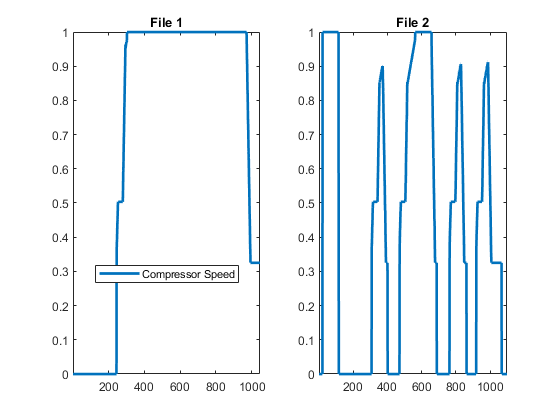

% Initialize a big figure to hold all subplots
figure;
numFiles = length(fileData); % Total number of files
numCols = ceil(sqrt(numFiles)); % Determine the number of columns (and rows) for the subplot grid
numRows = ceil(numFiles / numCols); % Ensure there are enough rows to accommodate all subplots

% Loop through all data files
for i = 1:length(fileData) 
    
    % Select data point
    select_data_point = fileData(i).wshp_power;
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
%     plot(select_data_point);
%     plot(fileData(i).tstat_spt(1:end)+1.5/1.8, 'LineWidth', 2, 'DisplayName', 'tstat+1.5F');hold on
%     plot(fileData(i).active_spt(1:end), 'LineWidth', 2, 'DisplayName', 'active');hold on
%     plot([fileData(i).sim_zone_temp(1:end)+1.5/1.8], 'LineWidth', 2, 'DisplayName', 'Tz,sim+1.5F');
%     plot([fileData(i).sim_zone_temp(1:end)], 'LineWidth', 2, 'DisplayName', 'Tz,sim');
%     plot(fileData(i).acc_error);
    plot(fileData(i).comp_spd, 'LineWidth', 2, 'DisplayName', 'Compressor Speed');
%     plot(fileData(i).error, 'LineWidth', 2);
%     scatter(1:numel(fileData(i).error), sort(fileData(i).error), '.');
%     yyaxis left
%     plot(fileData(i).tstat_spt(1:end-1)+1.5/1.8);hold on
%     plot(fileData(i).active_spt(2:end));hold on
%     plot(fileData(i).active_spt_offset);
%     plot(fileData(i).active_spt); hold on
%     plot(fileData(i).tstat_spt);
%     plot(fileData(i).error);
%     yyaxis right
%     plot(fileData(i).wshp_power);
%     plot(diff(fileData(i).tstat_spt(1:end-1)+1.5/1.8));
%     plot(fileData(i).comp_spd);
%     plot(fileData(i).sim_zone_temp);
%     plot([diff(fileData(i).comp_spd);0]);hold on
%     plot([1,length(fileData(i).comp_spd)], [0,0]);
    title(sprintf('File %d', i));
    
    if i == 1
        legend('Location', 'best');
    end
    
    % Adjust the limits and appearance as necessary
    xlim([1, length(select_data_point)]);
    
end

## 🏗️ Virtual testbed development

### 🧩 Prepare data

% % Number of files in fileData
% numFiles = length(fileData);
% 
% % Random exclude
% numExcludes = 4;
% excludeIndices = randperm(numFiles, numExcludes);
% 
% % Select data
% excludeIndices = [11];   % Override with manual select
% selectIndex = ~ismember(1:numFiles, excludeIndices);
% selectData = fileData(selectIndex);
selectData = fileData;

% Initialize feature and targets
x1 = [];
x2 = [];
x3 = [];
x4 = [];
x5 = [];
x6 = [];
xy1 = [];
xy2 = [];
y1 = [];
y2 = [];
y3 = [];
y4 = [];

% Combine data from selectData
for i = 1:length(selectData)
    x1 = [x1;selectData(i).error];
    x2 = [x2;selectData(i).acc_error];
    x3 = [x3;selectData(i).inlet_water_temp];
    x4 = [x4;selectData(i).return_air_temp];
    x5 = [x5;selectData(i).return_air_hr];
    x6 = [x6;selectData(i).sim_zone_temp];
    xy1 = [xy1;selectData(i).comp_spd];
    xy2 = [xy2;selectData(i).fan_spd];
    y1 = [y1;selectData(i).wshp_power];
    y2 = [y2;selectData(i).sen_load];
    y3 = [y3;selectData(i).lat_load];
    y4 = [y4;selectData(i).air_cfm];
end

### 🕸️ Visualize data distribution

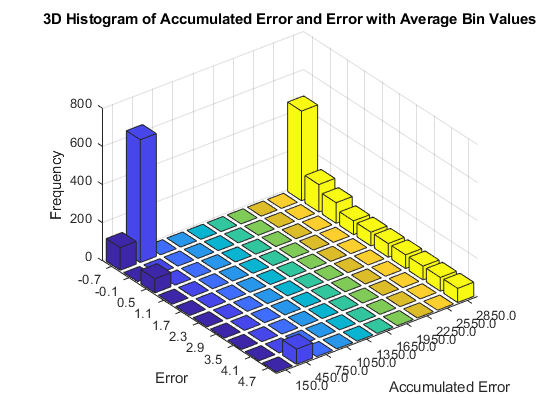

% x
% xval = x1; xval_label = 'Error';
xval = x2; xval_label = 'Accumulated Error';

% y
% yval = y1; yval_label = 'Power';
% yval = x2; yval_label = 'Accumulated Error';
yval = x1; yval_label = 'Error';

% Create a 2D histogram data
[N, C] = hist3([xval, yval], [10, 10]); % Adjust [10, 10] for different bin sizes

% Plot the 3D histogram using bar3
figure;
bar3Handle = bar3(N);
xlabel(xval_label);
ylabel(yval_label);
zlabel('Frequency');
title(['3D Histogram of ' xval_label ' and ' yval_label ' with Average Bin Values']);

% Set the tick labels to the bin centers, rounded to 1 decimal place
xticks(1:length(C{1}));
xticklabels(arrayfun(@(x) num2str(x, '%.1f'), C{1}, 'UniformOutput', false));
yticks(1:length(C{2}));
yticklabels(arrayfun(@(y) num2str(y, '%.1f'), C{2}, 'UniformOutput', false));

% Limit the x and y axes - set your desired limits here
xlim([0.5 length(C{1})+0.5]); % Limits for x-axis based on the number of bins
ylim([0.5 length(C{2})+0.5]); % Limits for y-axis based on the number of bins

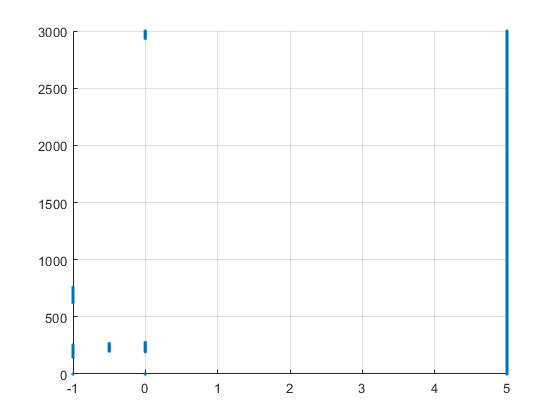


% 2D distribution
figure;
scatter(x1,x2, '.');
grid on